Daniel Sklyar

Homework #5

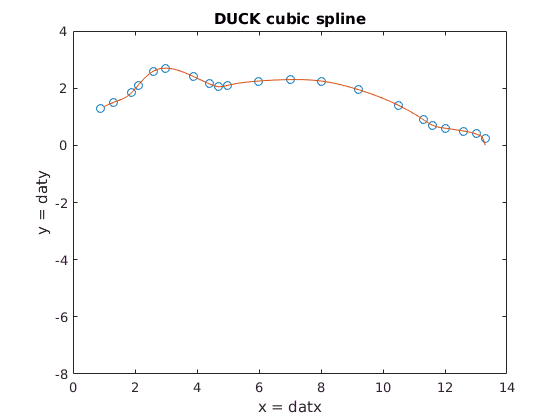


datx = [.9, 1.3, 1.9, 2.1, 2.6, 3.0, 3.9, 4.4, 4.7, 5.0, 6.0, 7.0, 8.0, 9.2, 10.5, 11.3, 11.6, 12.0, 12.6, 13.0, 13.3]        ; % FILL THE BLANK
daty = [1.3, 1.5, 1.85, 2.1, 2.6, 2.7, 2.4, 2.15, 2.05, 2.1, 2.25, 2.3, 2.25, 1.95, 1.4, .9, .7, .6, .5, .4, .25 ]        ; % FILL THE BLANK
x    = 1.0:0.1:13.3       ; 


plot(datx,daty,'o',x,cubic_spline(x,datx,daty));

axis([0 14 -8 4]);
title('DUCK cubic spline');
xlabel('x = datx');
ylabel('y = daty');

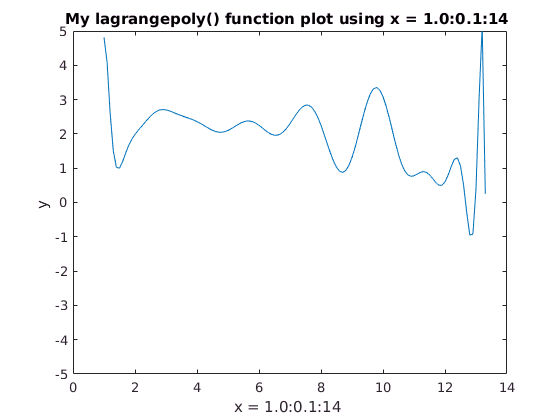


y = lagrange_poly(x,datx,daty);
figure(2)
plot(x,y), hold on;
title('My lagrangepoly() function plot using x = 1.0:0.1:14 ');
ylabel('y ');
xlabel('x = 1.0:0.1:14 ');
ylim([-5 5]);
hold off; 

function [sol] = lagrange_poly(x,datx,daty)
    sol = 0;                            % set return value [sol] to zero
    num = size(datx,2);                 % get length of datx array
    mat = ones(num,size(x,2));          % generate matrix size(datx,2) X size(daty,2)
                                        % using ones() in order to multiply 1*newval
    for i = 1:num                       % loop 1 tru colms
        for j = 1:num                   % loop 2 tru rows
            if i ~= j                   % if x_i != x_j
                % mat(i,:) -> all elements in the ith row 
                % (x - x_j) / (f(x_i) - f(x_j)) with [num] as degree
                mat(i,:) = mat(i,:).*(x - datx(j))./(datx(i)-datx(j));
            end
        end
    end
    for i = 1:num
        %Multiply Ln polynomials by the f(xn) given by [daty] and xn by [datx]
        sol = sol + daty(i) .* mat(i,:);
    end
end
function S = cubic_spline(x,datx,daty)
    %function that computes the natural cubic spline interpolant of a function given its value at some points
    %INPUTS:
    %x is the set of points on which we interpolate
    %datx is the initial set of points: x_0, x_1,..., x_n
    %daty is the initial set of point f(x_0), f(x_1),...,f(x_n)
    %OUTPUTS:
    %S is the cubic spline interpolant of f evaluated at x
    n = length(datx);
    a = zeros(n,1);
    % --------------------------
    % FILL THE BLANK IF NEEDED
    % --------------------------
    h = zeros(n,1);
    alpha = zeros(n,1);
    l = ones(n,1);
    m = zeros(n,1);
    z = zeros(n,1);
    c= zeros(n,1);
    
    for j = 1: n
        % Set a_j = f(x_j)
        a(j) = daty(j);
    end
    for j = 1: n-1
        % Set h_j = x_{j+1} - x_j
        % --------------------------
      h(j)=datx(j+1)-datx(j);
        % --------------------------
    end
    %--------------------------------------------------
    % Solve the system to find c_j and replace to find b_j and d_j
    %--------------------------------------------------
    % Look into your textbook for more information on that part
    for j = 2: n-1
        alpha(j) = (3/h(j))* (a(j+1) -a(j)) - (3/h(j-1))* (a(j) -a(j-1));
    end
    for j = 2:n-1
        l(j) = 2*(datx(j+1) - datx(j-1)) - h(j-1)*m(j-1);
        m(j) = h(j)/l(j);
        z(j) = (alpha(j) - h(j-1)*z(j-1))/l(j);
    end
    %l(n+1) = 1;
    %--------------------------------------------------
    %Update the value of b_j, c_j, d_j 
    for i=n-1:-1:1
        
        c(i) = z(i) - m(i)*c(i+1);
         b(i)= ( a(i+1)-a(i)) / (h(i) ) - h(i)*( c(i+1)+2*c(i) )/3 ;
         d(i)=(c(i+1)-c(i)) / (3*h(i));
    end

    %Define the entire cubic spline interpolant on the set of points x
    N = length(x);
    S = zeros (N,1);
    for  k =1:N
        for j = 1:n-1
            %Define x_j and x_j+1
            xj  =datx(j); % FILL THE BLANK
           
           xjp =datx(j+1); % FILL THE BLANK            
            if xj<=x(k) && x(k)<xjp
                % Set S(x) now that a_j,b_j,c_j,d_j are known
                % Recall that S(x) = S_j(x) on [x_j, x_j+1]
                % -------------------------
                % FILL THE BLANK
                
                S(k)=a(j)+b(j)*(x(k)-datx(j))+c(j)*(x(k)-datx(j))^2+d(j)*(x(k)-datx(j))^3;
                % -------------------------- 
            else
                % --------------------------
                % FILL THE BLANK
                % --------------------------
                S(k)==0;
             
               
            end %end loop if

        end %end loop j
    % Set the value of S(x) for the endpoint x_n 
        if x == datx(n)
        %  S(k) = ; % FILL THE BLANK
        S(k)=datx(n);
        end
    end % end loop k

    
end %end function